# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;


## Generate a random physical topology

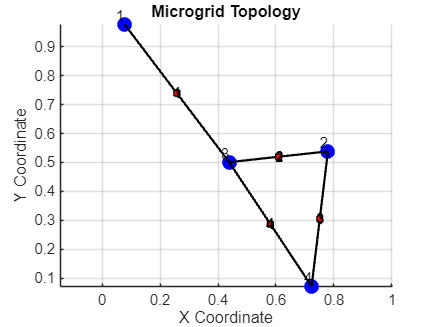

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
     1     1     0     1
     0     1     1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generatePhysicalTopology(numOfDGs, threshold);


%%%% Update the figure to show the assumed initial communication topology
% (A_ij matrix representa the communication topology)



## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.05;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.5;       % Capacitance % Decreasing this, increasing convergence speed

RL0 = 0.5;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance
IL0 = 0.5;        % Constant Current Load
LoadNoiseMean = 10;
LoadNoiseStd = 2;


for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 50;     % Line Resistance % Increasing this, the damping ratio decrease
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il coords adjMatrix
 % global DG Line B_il A_ij % Making some values as global variables

## Co-Design Process

parameters

BarGamma = 100000;    % Fixed value for gammaBar
isSoft = 0;      % Set to 1 to avoid the hard graph constraint

% pScalar = 1/(numOfDGs+numOfLines);
piScalar = 10^-2;
plScalar = 10^-3;

piVals = piScalar*ones(1,numOfDGs);
plVals = plScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

% Inside the function, you need to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

First Method: This Method computes the passivity indices for DGs and lines at the same time. 

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1




DG{1}

ans = struct with fields:
              R: 0.0384
              L: 0.0100
              C: 0.5538
              Y: 1.6090
             IL: 0.4643
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.0763 0.9780]
             P0: [3×3 double]
             K0: [-5.9607e+07 -2.2204e+06 -2.0187e+08]
             nu: -2.1457e+04
            rho: 5.3472e+03
    gammaTilde0: 774.1191


Line{1}

ans = struct with fields:
      R: 56.7605
      L: 0.0098
      A: -5.7880e+03
      B: 101.9730
     P0: 5.4672e+05
     nu: -9.8230e+05
    rho: 3.1647e+09


Second Method: This method first computes the DGs' passivity indices and use those properties to compute the Lines' passivity indices. 

% [DG, rhoTilde_i, nu_i, gammaTilde_i,statusDG] = designDGPassivity(DG, B_il,piVals);
% [Line, statusLine] = designLinePassivity(Line, DG, B_il, BarGamma, piVals,plVals,rhoTilde_i, nu_i);
%%%% Theoretically explain why this works in the paper, in a corollary (of Theorem 2).  
%%%% There is an imbalance

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal,K,C,BarC,H,P_iVal,P_lVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft);

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 153             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 299             
  Matrix variables       : 1 (scalarized: 1176)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                

%%%% Theoretically think about adding normalizing constraints trace(P_i)==1, trace(P_l)==1 constraint

K{1,1}

ans = 1.0e-03 *

         0         0         0
    0.5066   -0.2420   -0.1996
         0         0         0


K{1,3}

ans =          0         0         0
    0.0031    0.0041    0.0035
         0         0         0


K{3,4}

ans =          0         0         0
    0.0018    0.0024    0.0020
         0         0         0


K{1,2}

ans =          0         0         0
    0.0017    0.0018    0.0013
         0         0         0




% Initialized nominal and reference voltages
V_nom = 120;            % Nominal Voltage
V_ref = 48;             % Reference Voltage

% Scenario #1: Global Load Change
R_Global = 5;           % Global Load
ChangeGlobalLoad1 = 1;  % Connect Global Load #2
ChangeGlobalLoad2 = 3;  % Disconnect Global Load #2

% Scenario #1: Local Load Change
PlugOut = 4;            % Plug out Local load
PlugIn = 7;             % Plug in Local load

% % Scenario #3: Change of Reference Voltage:
% V_ref1 = 48;
% V_ref2 = 100;
% change_reference = 4;

## Generate Optimized Communication Topology

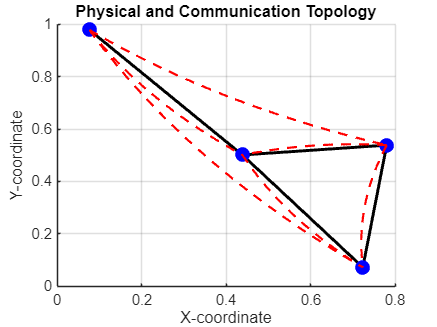

commMatrix =      0     1     1     1
     1     0     1     1
     1     1     0     1
     1     1     1     0


% Plot Communication Topology
[commMatrix] = generateCommunicationTopology(coords, A_ij, K)

#### The following functions are desgined to evaluate the effects of different parameters on the passivity indices of DGs and lines and their feasibilities

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()

Optimize pVals (Method 3)

% plotLocalControlDesign(DG, Line, B_il, BarGamma, numOfDGs, numOfLines);
% plotGlobalControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
% plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);
% plotTestBothFeasibility(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

Function to evaluate the effect of number of DGs and Threshold

% numDGsRange = 5:6;              % Example range for number of DGs
% thresholdRange = 0.1:0.1:1;     % Example range for threshold values
% pScalarRange = 0.01:0.01:10;    % Example range for pScalar values
% BarGamma = 5;                   % Fixed value for gammaBar
% isSoft = 1;                     % Set to 1 to use soft constraint

% [numOfDGs, threshold] = evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);